# E6 bis

#### Exercici 1

Calculeu l'histograma dels angles dels gradients d'una imatge (100x100 píxels) generada sintèticament que consisteixi en un degradat de grisos amb origen el centre de la imatge i amb forma de 'flam' gaussià (Two-dimensional Gaussian function).

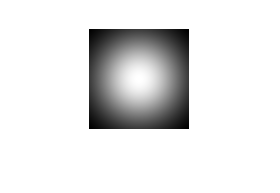

I = fspecial("gaussian",[100 100], 32);
imshow(I,[]);

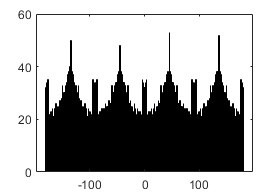


hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';
Gx = imfilter(I,hx);
Gy = imfilter(I,hy);

angle = atan2(Gx,Gy)*(180/pi); % radians a graus
histogram(angle,360);

#### Exercici 2

Es vol tenir una útil aplicació de visió per computador que ajudi a trobar a Odlaw, utilitzant el coneixement que la samarreta d’Odlaw està composta de franges negres i grogues. Amb aquest objectiu, caldrà crear una imatge que sigui una mena de mapa tèrmic; que indiqui on les franges negres i grogues (amb prou gruix) es troben. Elimineu les deteccions espúries (petites deteccions) i feu una superposició del mapa tèrmic (en vermell) amb la imatge original (en gris).

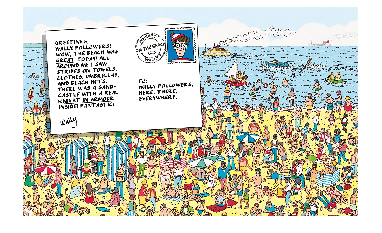

I = imread("wally.jpg");
[f c z] = size(I);
J = imcrop(I,[1 1 floor(c/2) floor(f/2)]);
imshow(J);

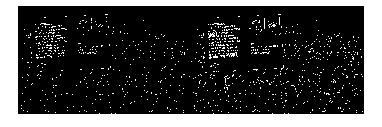


HSV = rgb2hsv(J);
H = HSV(:,:,1);
S = HSV(:,:,2);
V = HSV(:,:,3);

VB = V < 0.08;
H = (H > 0.10) & (H < 0.2);
%F = H | VB;
%S = S.*F;
%HSV(:,:,2) = S;
%RGB = hsv2rgb(HSV);
% imshow(RGB);

%imshow(VB);
SE = ones(7,3);
BC = imclose(VB,SE);
montage({VB,BC});

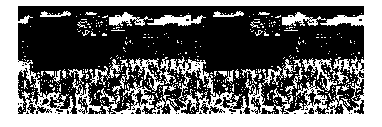


SE = ones(2,1);
YC = imclose(H,SE);
%imshow(YC);
montage({H,YC});

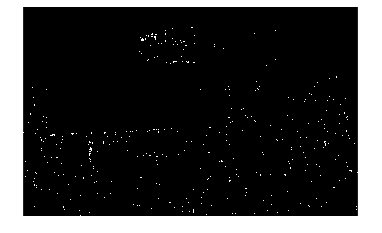


T = BC & YC;
imshow(T);

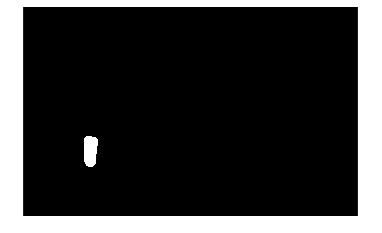


SE = ones(10,1);
TC = imclose(T,SE);
imshow(TC);

Res = bwareaopen(TC, 230);
%imshow(Res);

SE = fspecial("disk",20) > 0;
Res2 = imdilate(Res,SE);
imshow(Res2);

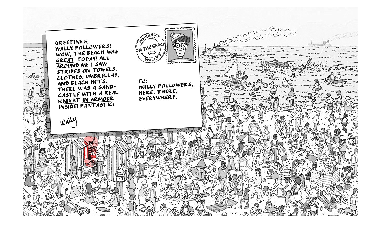


HSV = rgb2hsv(J);
H = HSV(:,:,1);
S = HSV(:,:,2);

H(Res2) = 0;  %taca vermella
S(not(Res2)) = 0; %fons sense color

HSV(:,:,1) = H;
HSV(:,:,2) = S;
RGB = hsv2rgb(HSV);
imshow(RGB);